%Task 1
x = [3, 11, 7, 0, -1, 4, 2]; nx = [-3:3];
h = [2, 3, 0, -5, 2, 1]; nh = [-1:4];
[y , ny] = conv_m(x, nx, h, nh)

y =      6    31    47     6   -51    -5    41    18   -22    -3     8     2


ny =     -4    -3    -2    -1     0     1     2     3     4     5     6     7


Picture of the manual solution has been given in the zip file provided

%Task 2
[A,freq] = audioread("speech.wav");
[B,freq2] = audioread("Large Long Echo Hall.wav");
B2 = B(:,1);
A2 = A(:,1);
Result = conv(B2,A2);
filename = "Beginning_13.wav";
audiowrite(filename, Result, freq2);

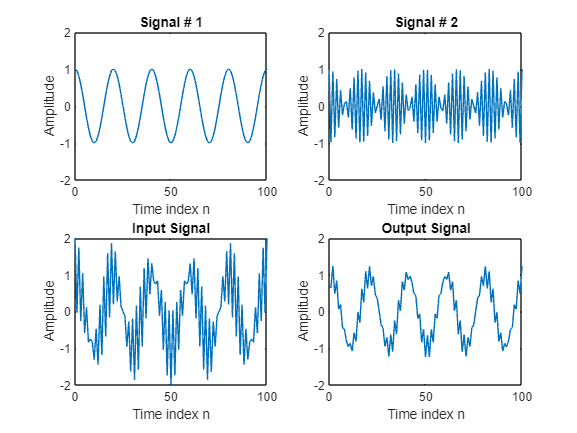

%Task 3
% Simulation of an M-point Moving Average Filter
% Generate the input signal
n = 0:100;
s1 = cos(2*pi*0.05*n); % A low frequency sinusoid
s2 = cos(2*pi*0.47*n); % A high frequency sinusoid
x = s1+s2;
% Implementation of the moving average filter
M = input('Desired length of the filter = ');
num = ones(1,M);
y = filter(num,1,x)/M;
% Display the input and output signals
clf;
subplot(2,2,1);
plot(n,s1);
axis([0, 100, -2, 2]);
xlabel('Time index n');
ylabel('Amplitude');
title('Signal # 1');
subplot(2,2,2);
plot(n,s2);
axis([0, 100, -2, 2]);
xlabel('Time index n'); ylabel('Amplitude');
title('Signal # 2');
subplot(2,2,3);
plot(n,x);
axis([0, 100, -2, 2]);
xlabel('Time index n'); ylabel('Amplitude');
title('Input Signal');
subplot(2,2,4);
plot(n,y);
axis([0, 100, -2, 2]);
xlabel('Time index n'); ylabel('Amplitude');
title('Output Signal');

axis;

I believe this is a high pass filter, as it removes the signal#2 high frequency and brings it closer to the lower frequency and form of signal 1, we can observe that it looks more closer to that input signal as well. 

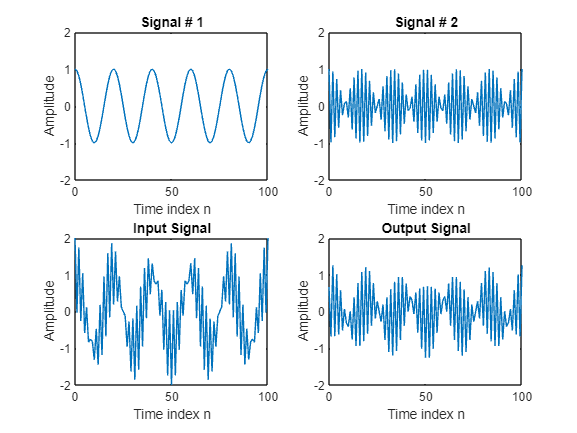

%Task 3.2 
n = 0:100;
s1 = cos(2*pi*0.05*n); % A low frequency sinusoid
s2 = cos(2*pi*0.47*n); % A high frequency sinusoid
x = s1+s2;
M = input('Desired length of the filter = ');
n1=0:M-1;
num=(-1).^n1.*ones(1,M);

y = filter(num,1,x)/M;
clf;
subplot(2,2,1);
plot(n,s1);
axis([0, 100, -2, 2]);
xlabel('Time index n');
ylabel('Amplitude');
title('Signal # 1');
subplot(2,2,2);
plot(n,s2);
axis([0, 100, -2, 2]);
xlabel('Time index n'); ylabel('Amplitude');
title('Signal # 2');
subplot(2,2,3);
plot(n,x);
axis([0, 100, -2, 2]);
xlabel('Time index n'); ylabel('Amplitude');
title('Input Signal');
subplot(2,2,4);
plot(n,y);
axis([0, 100, -2, 2]);
xlabel('Time index n'); ylabel('Amplitude');
title('Output Signal');

axis;

This has now become a low pass filter. As can be observed, when Signal 1 and 2 were combined, and then went through the filter, it can be observed that the lower frequency was removed and the output signal looks closer to signal #2. Thus it can be deducted that this is a low pass filter.

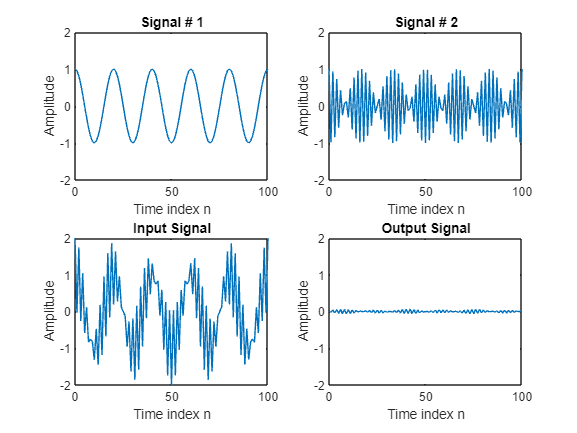

%Task 3.3 Changing the value of Ms and observing 
n = 0:100;
s1 = cos(2*pi*0.05*n); % A low frequency sinusoid
s2 = cos(2*pi*0.47*n); % A high frequency sinusoid
x = s1+s2;
M = input('Desired length of the filter = ');
n1=0:M-1;
num=(-1).^n1.*ones(1,M);

y = filter(num,1,x)/M;
clf;
subplot(2,2,1);
plot(n,s1);
axis([0, 100, -2, 2]);
xlabel('Time index n');
ylabel('Amplitude');
title('Signal # 1');
subplot(2,2,2);
plot(n,s2);
axis([0, 100, -2, 2]);
xlabel('Time index n'); ylabel('Amplitude');
title('Signal # 2');
subplot(2,2,3);
plot(n,x);
axis([0, 100, -2, 2]);
xlabel('Time index n'); ylabel('Amplitude');
title('Input Signal');
subplot(2,2,4);
plot(n,y);
axis([0, 100, -2, 2]);
xlabel('Time index n'); ylabel('Amplitude');
title('Output Signal');

axis;

Increasing the value smoothens the output signal more and more, but it leads to its amplitude getting smaller and smaller as a result of that, until it thins out very drastically if you set the M value to 100.  If you have M = 0, there will be no output signal, and if M = 1, it will just give you the "input signal" as it is. 